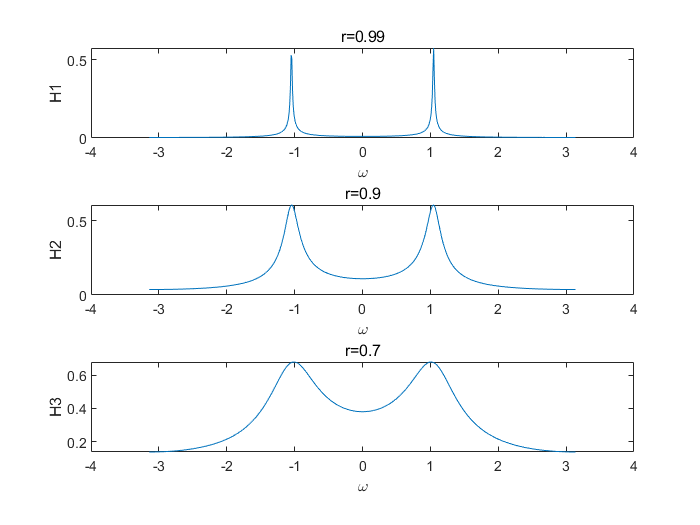

clear;close all;clc;
j=sqrt(-1);
w=-pi:0.01:pi;
z=exp(j*w);
r1=0.99;
r2=0.9;
r3=0.7;
H1=(1-r1)./(1-2*r1*cos(pi/3).*z.^(-1)+r1.^2.*z.^(-2));
H2=(1-r2)./(1-2*r2*cos(pi/3).*z.^(-1)+r2.^2.*z.^(-2));
H3=(1-r3)./(1-2*r3*cos(pi/3).*z.^(-1)+r3.^2.*z.^(-2));
figure(1);
subplot(311);
plot(w,abs(H1));xlabel('\omega');ylabel('H1');title('r=0.99');
subplot(312);
plot(w,abs(H2));xlabel('\omega');ylabel('H2');title('r=0.9');
subplot(313);
plot(w,abs(H3));xlabel('\omega');ylabel('H3');title('r=0.7');

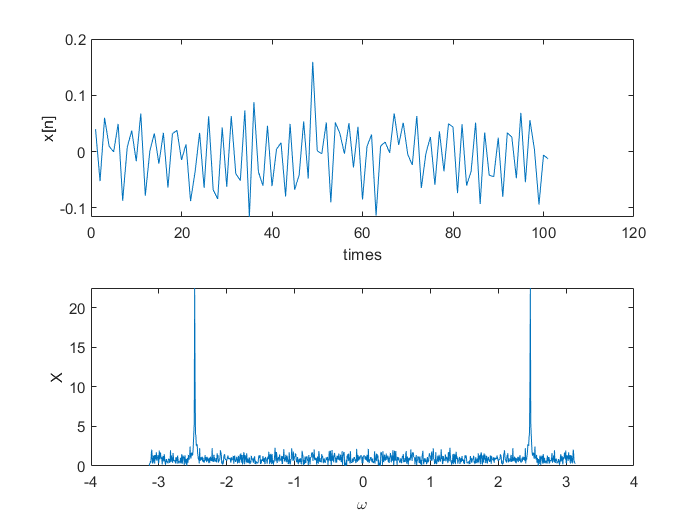

load pcm.mat
% sound(pcm)

[X,w]=DTFT(pcm(100:1100),0);
figure(2);
subplot(211)
plot(pcm(100:200));xlabel('times');ylabel('x[n]');
subplot(212);
plot(w,abs(X));xlabel('\omega');ylabel('X');

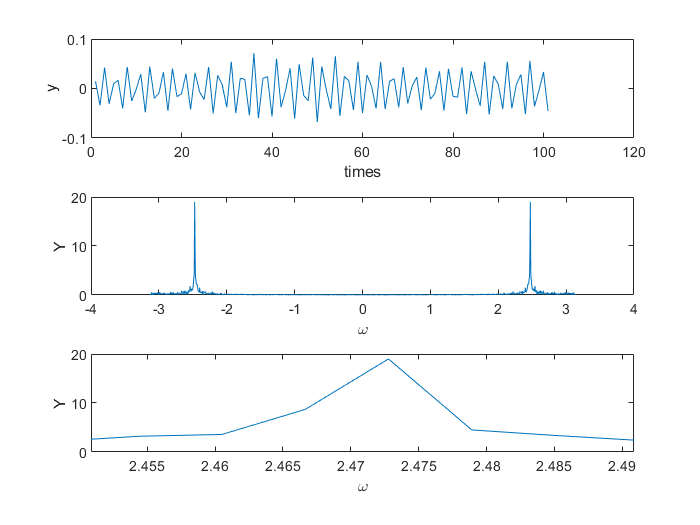

y_filter=IIRfilter(pcm);
sound(y_filter);

figure(3);
subplot(311);
plot(y_filter(100:200));xlabel('times');ylabel('y');
subplot(312);
[X1,w1]=DTFT(y_filter(100:1100),0);
plot(w1,abs(X1));xlabel('\omega');ylabel('Y')

subplot(313);
theta=(3146/8000)*2*pi;
plot(w1,abs(X1));xlabel('\omega');ylabel('Y');
xlim([theta-0.02 theta+0.02]);